# Part2: 過去台風データの分析

Copyright 2022 The MathWorks, Inc

ドキュメンテーションの「[地理密度プロットでの台風の軌跡データの表示](https://jp.mathworks.com/help/matlab/creating_plots/view-cyclone-track-data-in-geographic-density-plot.html)」で紹介されているデータを使用します。

load cycloneTracks
data = cycloneTracks;

もし data_NORU.csv と同様に台風毎にデータが個別に用意されている場合は、`datastore` を使用した以下の方法で全部読み込むことができます。以下では全ファイルが dataset というフォルダ内に保存されている想定です。

## 台風のグレード毎の気圧値

データでは以下の区分けで、その時々の Grade がついています。

- 2 : Tropical Depression (TD)

- 3 : Tropical Storm (TS)

- 4 : Severe Tropical Storm (STS)

- 5 : Typhoon (TY)

- 6 : Extra-tropical Cyclone (L)

- 7 : Just entering into the responsible area of RSMC Tokyo-Typhoon Center

- 8 : Not used

- 9 : Tropical Cyclone of TS intensity or higher

ここでは Grade 毎に気圧値（Pressure) がどのような値を持つかを調べます。

% グループ要約の計算
newTable = groupsummary(data,"Grade",["median","min"],"Pressure");
newTable.GroupCount = []

newTable = 6×3 table
    Grade    median_Pressure    min_Pressure
    _____    _______________    ____________

      2           1004              990     
      3            994              980     
      4            980              965     
      5            950              885     
      6            996              948     
      7            993              945     


最も台風が発達した状態（Grade = 5）で気圧が最も低く直感とも合うことが分かります。

## 最大風速の変化

その年に発生した台風の最大風速がどのように変化しているかを見てみます。

% グループ要約の計算
newTable2 = groupsummary(data,"Time","year","max","WindSpeed");
newTable2.GroupCount = []

newTable2 = 11×2 table
    year_Time    max_WindSpeed
    _________    _____________

      2007            110     
      2008            115     
      2009            115     
      2010            125     
      2011            105     
      2012            110     
      2013            125     
      2014            115     
      2015            115     
      2016            120     
      2017            100     


変化をプロットしてみると、2007年 - 2017年では傾向は見られません。

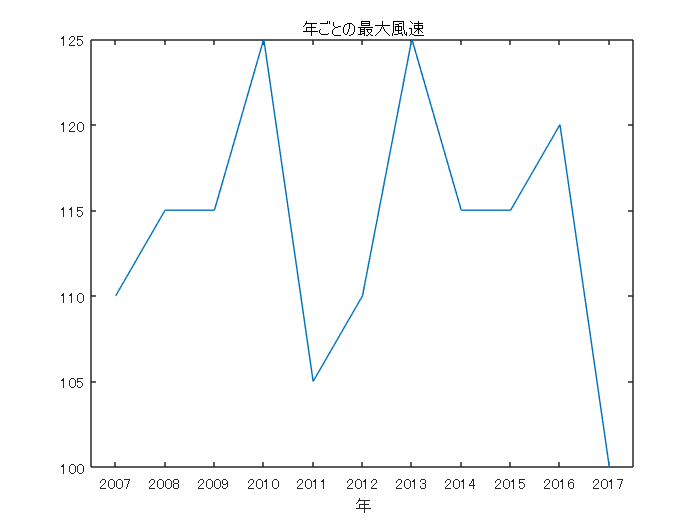

plot(newTable2.year_Time,newTable2.max_WindSpeed)

title('年ごとの最大風速')
xlabel('年')

## 月ごとの発生回数

月ごとの台風発生回数を集計します。`month(x(1))` というカスタム関数で集計していますが、これは台風の最初の情報の時点での月をその台風の発生月と定義しています。

% グループ要約の計算
newTable3 = groupsummary(data,"ID",@(x) month(x(1)),"Time");
newTable3.GroupCount = [];

ヒストグラム化してみるとこちらも経験にあっており、7月 - 9月に台風が増加していることが見て取れます。

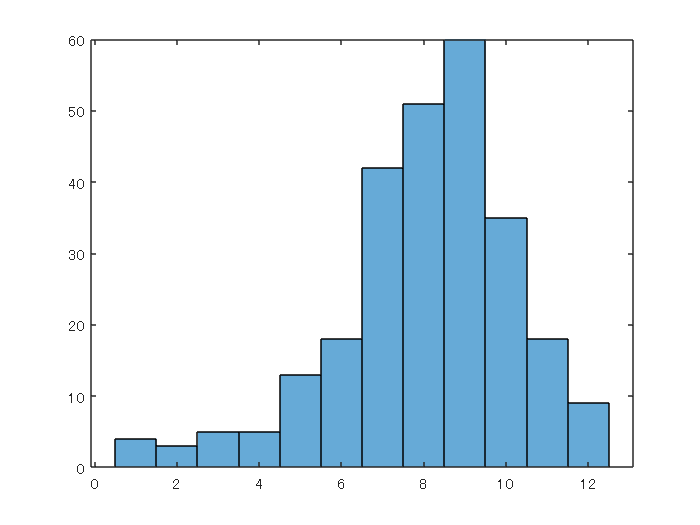

histogram(newTable3.fun1_Time)

## 月ごとの経路の違い

月ごとの経路の違いを可視化します。for ループ内で `drawnow` を使うことでアニメーションを作成します。そのまま動画（mp4, gif）として出力可能です。

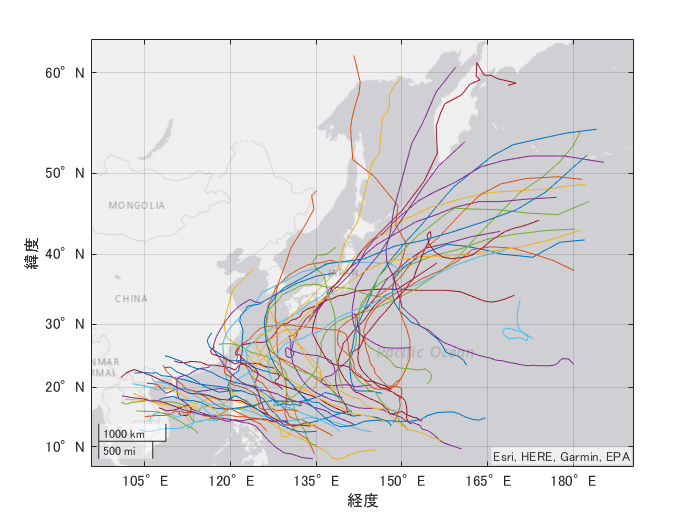

month2show = 9;
idx = newTable3.fun1_Time == month2show;
ID2show = newTable3.ID(idx);

subdata = data(ismember(data.ID,ID2show),:);

uniqueID = unique(subdata.ID,'stable');
for ii = 1:length(uniqueID)
    tmp = subdata(subdata.ID == uniqueID(ii),:);
    geoplot(tmp.Latitude, tmp.Longitude)
    hold on 
    drawnow
end
hold off